# Fixpunktiteration für lineare Gleichungssysteme

Wir betrachten eine Integralgleichung wie in Abschnitt 3.1.2 (Beispiel 3.7):


$$u(x) + \lambda \int_0^1 \cos (xt) u(t) \,dt =2, ~~x\in [0,1],$$


mit einem Parameter $\lambda >0$ (in Beispiel 3.7 gilt $\lambda=2$). Diskretisierung wie in Beispiel 3.7 führt auf ein Gleichungssystem 


$$\quad Ax=b$$


mit $A=I + \lambda B, ~~b_{i,j}:=h\cos(t_it_j),~~t_k:=(k-\frac12)h,~~1\leq i,j \leq n,~~h:=\frac{1}{n},~~b=(2,2,\ldots,2)^T$.

Die Anzahl der Gitterpunkte $n\in\mathbb N$ wird gewählt. Die Matrix $B\in\mathbb R^{n\times n}$ und rechte Seite $b\in\mathbb R^n$ werden berechnet.

n=200;
B=makeB(n);
b=2*ones(n,1);

Wir wählen einen Wert für den Parameter $\lambda$:

lambda=0.55;

 Zur Lösung des Gleichungssystems betrachten wir die Fixpunktiteration

$x_{k+1}= \Phi(x_k), \quad \Phi(x)=-\lambda Bx +b
$,

siehe Übung 5.10. Für $\lambda \in (0,1)$ sind die Voraussetzungen des Banachschen Fixpunktsatzes, mit Kontraktionszahl $L=\lambda$ in der Maximumnorm $\|\cdot\|_\infty$, erfüllt. Wir verwenden diese Fixpunktiteration mit Toleranz $\epsilon=10^{-8}$, maximale Iterationszahl $k_\max=500$ und Startvektor $x_0=0$.

Das Stoppkriterium basiert auf der a-posteriori Schranke:  $\|x_k-x^\ast\|_\infty \leq \frac{L}{1-L} \|x_k-x_{k-1}\|_\infty =:E_k$

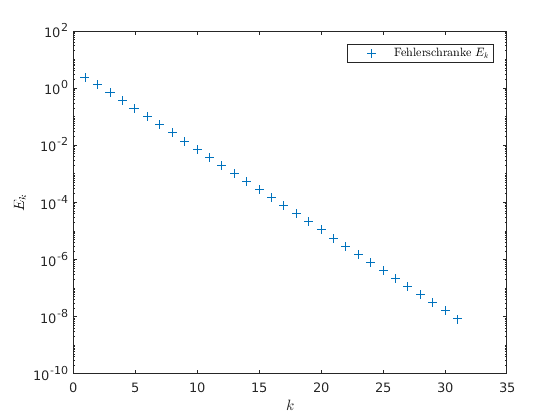

epsilon=10^(-8);
kmax=500;
xold=zeros(n,1); E=zeros(kmax,1);
k=0;
Fehlerschranke=1;
while ((k < kmax) && (abs(Fehlerschranke) >epsilon))
    xnew= -lambda*B*xold+b;
    Fehlerschranke= lambda/(1-lambda)*norm(xnew-xold,inf);
    xold=xnew;
    k=k+1;
    E(k)=Fehlerschranke;
end;
semilogy(E(1:k),'+');
leg1=legend('Fehlerschranke $E_k$'); set(leg1,'Interpreter','latex');
xlabel('$k$','Interpreter','latex'); ylabel('$E_k$','Interpreter','latex');

fprintf('\n Iteration beendet nach k Iteration:\n');


 Iteration beendet nach k Iteration:


k

k =     31


fprintf('\n A-posteriori Fehlerschranke:\n');


 A-posteriori Fehlerschranke:


Fehlerschranke

Fehlerschranke =    8.5201e-09


# Aktivität:

- Variieren Sie  $\lambda \in (0,1)$ und den $n$-Wert. (Wie) hängt die Anzahl der Iterationen $k$ von dem $n$-Wert  und von $\lambda$ ab?

- Wie hoch ist der Aufwand pro Iteration der Fixpunktiteration? In welchen Fällen ist der Aufwand dieses Verfahrens (erheblich) geringer als der Aufwand der Gauß-Elimination (oder des Cholesky-Verfahrens) zur Lösung des Gleichungssystems $Ax=b$?

- Was passiert wenn man $\lambda >1$ wählt? Darf man aus den Ergebnissen in der Grafik schließen, dass die Fixpunktiteration für $\lambda >1$ nicht konvergiert?

function B=makeB(n)
h=1/n;
B=zeros(n,n);
for i=1:n
    ti=(i-0.5)*h;
     for j=1:n
        tj=(j-0.5)*h;
         B(i,j)=h*cos(ti*tj);
     end;
end;
end